% function [cov_matrix, ev1, ev2] = cov_analysis(raster_data, stimulus, window, fs)
% 
raster_data = P(1).raster(:,start_stim:stop_stim);
stimulus = -P(1).antennal_movement(:,start_stim:stop_stim);
% stimulus = stimulus - mean(stimulus,2);

% raster_data = WN_Repeat_Matrix';
% stimulus = wn_stim_matrix';
window = 0.03;
% fs = 8e4;

[NstimPriors,~] = size(raster_data);
STA_freq = [];
numSpikes = sum(raster_data,'all');
all_spike_triggers = nan([numSpikes window*fs+1]);
k=1;
spike_triggers = [];

for i=1:NstimPriors
    spike_locs = find(raster_data(i,:)==1);
    if isempty(spike_locs)
        continue;
    end
    for j=1:length(spike_locs)
        if (spike_locs(j)-window*fs)>= 0
            
            spike_triggers = stimulus(1,(spike_locs(j)-window*fs):spike_locs(j));
%             spike_triggers = spike_triggers-mean(spike_triggers);
            %             plot(STA); hold on;
%             all_spike_triggers = [all_spike_triggers; spike_triggers];
            all_spike_triggers(k,:) = spike_triggers;
            k=k+1;
        end
    end

end
TF=isnan(all_spike_triggers(:,1));
all_spike_triggers(TF,:)=[];


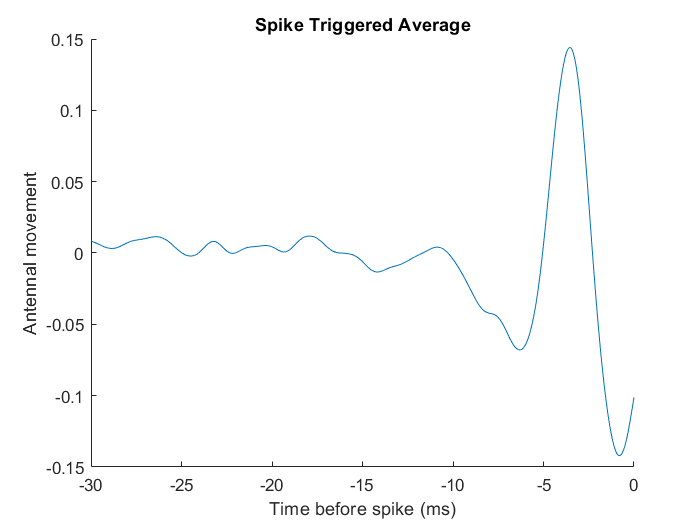


STA = mean(all_spike_triggers,1);
t= linspace(-window*1000, 0, length(STA));
figure;
plot(t, STA);
title('Spike Triggered Average');
% for i=1:5
%     figure;
%     plot(t, all_spike_triggers(i,:), 'k');
%     box off;
%     ax = gca;
%     ax.YAxis.Visible = "off";
%     ax.XAxis.Visible = "off";
%     
% end
% title('Spike triggers')
xlabel('Time before spike (ms)');
ylabel('Antennal movement');
ax = gca;
ax.Box = "off";

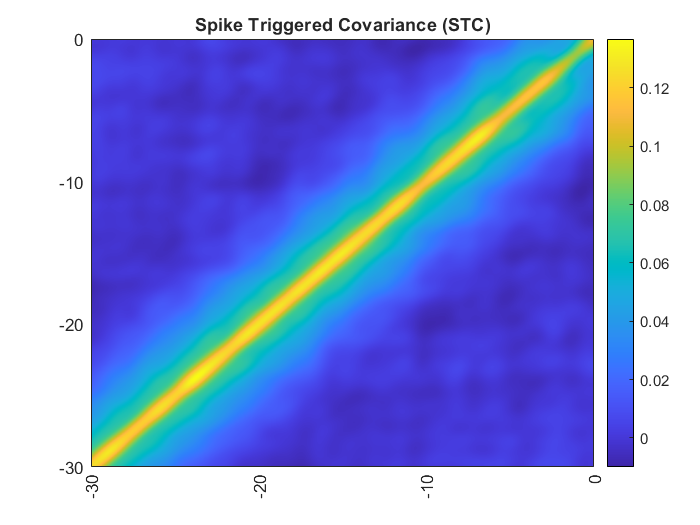


% cov_matrix = cov((all_spike_triggers-STA)');
nspikes = size(all_spike_triggers,1);
% A = (all_spike_triggers-STA);
cov_matrix = (1/(nspikes -1))*(all_spike_triggers-STA)'*(all_spike_triggers-STA);
% cov_matrix = (1/(nspikes -1))*((all_spike_triggers'*all_spike_triggers)-(STA'*STA));

figure;

h = heatmap((cov_matrix), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Spike Triggered Covariance (STC)");

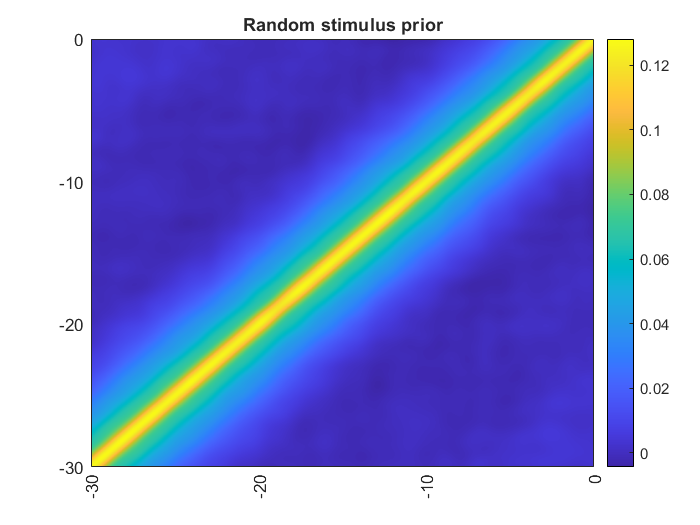

pattern_length = size(all_spike_triggers,2);
NstimPriors = size(all_spike_triggers,1);
stimulus_prior = zeros([NstimPriors pattern_length]);
r = randi([1 (length(stimulus)-pattern_length)],1,NstimPriors);
for j=1:NstimPriors
    stimulus_prior(j,:) = stimulus(randperm(size(stimulus,1),1),r(j):r(j)+pattern_length-1);
end

% for i=1:4
%     figure;
%     plot(t, stimulus_prior(i,:));
%     box off;
%     ax = gca;
%     ax.YAxis.Visible = "off";
%     ax.XAxis.Visible = "off";
%     
% end

% stimulus_prior = stimulus_prior(randperm(m),randperm(n));
% stimulus_prior = all_spike_triggers(randperm(m),randperm(n));
avg_stim = mean(stimulus_prior,1);
% stim_prior_cov = cov(stimulus_prior);
stim_prior_cov = (1/(NstimPriors -1))*(stimulus_prior-avg_stim)'*(stimulus_prior-avg_stim);
figure;
h = heatmap((stim_prior_cov), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Random stimulus prior");

## Eigen value of prior covariance matrix

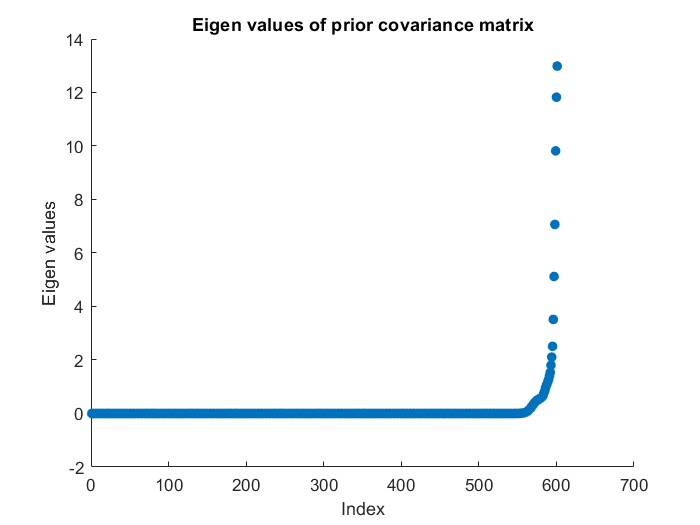


[V,D] = eig(stim_prior_cov);
% [V,D] = eig(cov_matrix);

[~, ind] = sort(real(diag(D)), 'descend');
% [~, ind] = sort(real(diag(D)), 'descend');
Ds = D(ind,ind);
Vs = V(:,ind);

eVal = diag(Ds);
eVec1 = Vs(:,1);
eVec2 = Vs(:,2);
% evInd = find(ev~=0);
figure;
plot(sort(real(diag(D)),'ascend'), '.',"MarkerSize",20);
% plot(sort(real(eVal),'descend'))
title('Eigen values of prior covariance matrix');
ylabel('Eigen values');
xlabel('Index');
ax = gca;
ax.Box = "off";

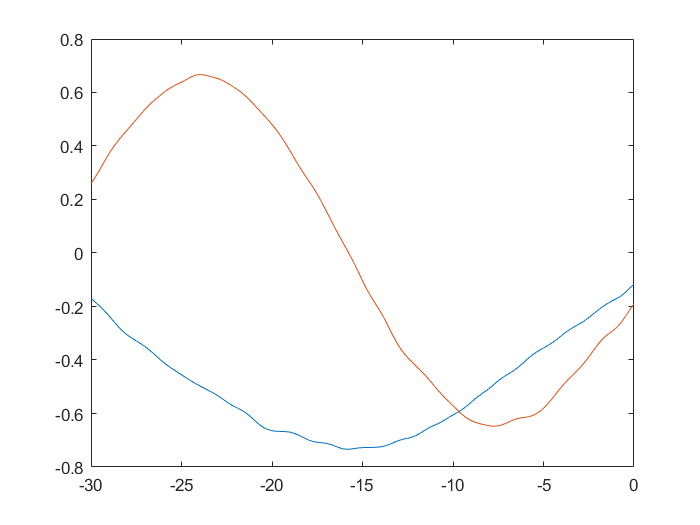


t= linspace(-window*1000, 0, length(STA));
plot(t,Vs(:,1)*eVal(1)); hold on;
plot(t,Vs(:,2)*eVal(2));

## Calculating psuedo inverse of prior cov matrix (CpPseudoInv)

idx = find(abs(real(diag(D)))<0.001);
DsPseudoInv = 1./diag(D);
DsPseudoInv(idx) = 0;

CpPseudoInv = DsPseudoInv.*(V*V');

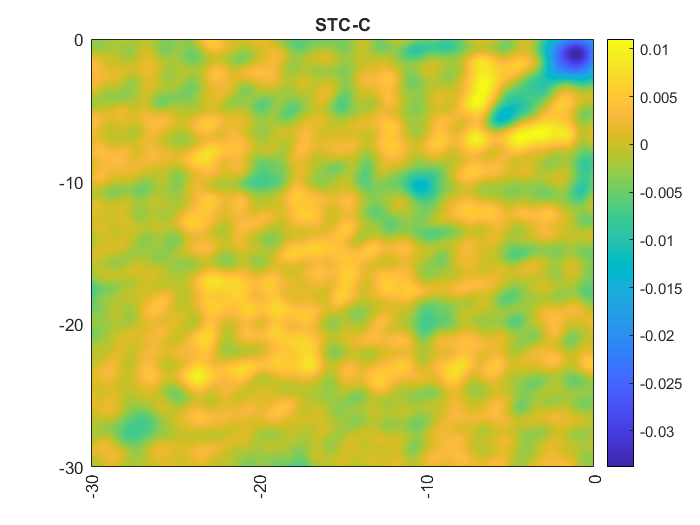

diff_cov = (cov_matrix - stim_prior_cov) ; 
figure;
h = heatmap(diff_cov, 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("STC-C");


% for i=1:3
%     figure;
%     plot(t, diff_cov(i,:));
%     box off;
%     ax = gca;
%     ax.YAxis.Visible = "off";
%     ax.XAxis.Visible = "off";
%     
% end


## Stimulus whitening and whitened STA

% whitened_stim = (stim_prior_cov^-0.5)*all_spike_triggers';

whitened_sta = STA*real(CpPseudoInv);
figure;
plot(whitened_sta)

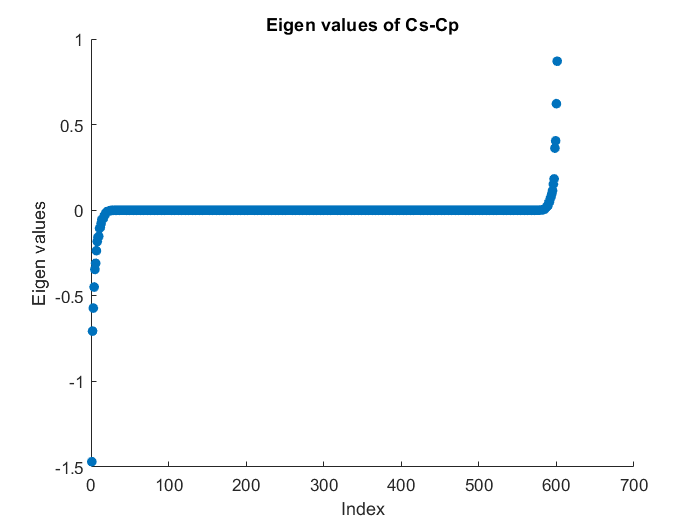


[V,D] = eig(diff_cov);
% [V,D] = eig(cov_matrix);

[~, ind] = sort(abs(real(diag(D))), 'descend');
% [~, ind] = sort(real(diag(D)), 'descend');
Ds = D(ind,ind);
Vs = V(:,ind);

eVal = diag(Ds);
eVec1 = Vs(:,1);
eVec2 = Vs(:,2);
% evInd = find(ev~=0);
figure;
plot(sort(real(diag(D)),'ascend'), '.',"MarkerSize",20);
% plot(sort(real(eVal),'descend'))
title('Eigen values of Cs-Cp');
ylabel('Eigen values');
xlabel('Index');
ax = gca;
ax.Box = "off";

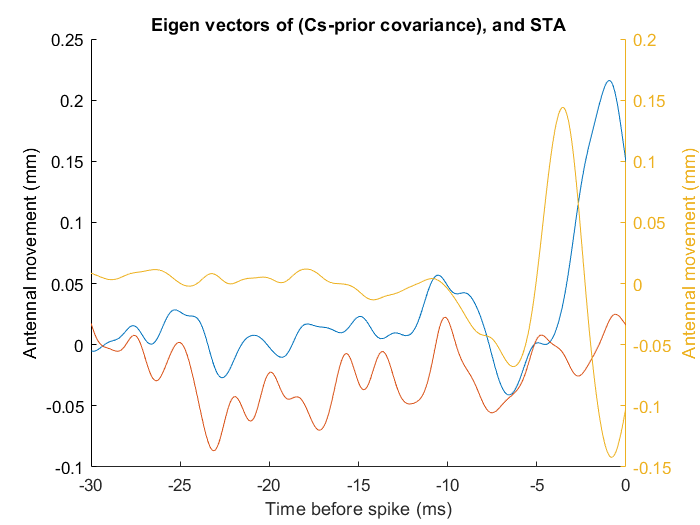



t= linspace(-window*1000, 0, length(STA));

% figure;
% plot(t, STA-STA(1,1),t, 0.01*sum(Vs(:,1:2),2));
% title('Spike Triggered Average');
% xlabel('Time before spike (ms)');
% ylabel('Antennal movement');
% legend("STA", "Scaled sum of 2 eigen vectors", 'Location',"best")
% diag_Ds = diag(Ds);
% plot(t, Vs(:,1:2).*diag_Ds(1:2));
plot(t,Vs(:,1)*eVal(1)); hold on;
plot(t,Vs(:,2)*eVal(2));
ylabel('Antennal movement (mm)');
% plot(t,sum(Vs(:,1:2),2));
yyaxis right; plot(t,STA); ylabel("STA");
% legend("EV1","EV2","Sum of EVs", "STA", 'Location',"best");
% plot(t,Vs(:,1:2));
ax = gca;
% ax.YAxis.Visible = 'off'
ax.Box = 'off';

% legend("STA","EV1","EV2");
title('Eigen vectors of (Cs-prior covariance), and STA');
xlabel('Time before spike (ms)');
ylabel('Antennal movement (mm)');


% figure;
% plot(60*diff(Vs(:,2))); hold on;
% plot(Vs(:,1));

% corrcoef(STA, eVec1)
% corrcoef(eVec2+eVec1,STA)


## Projection of stimulus patterns onto eigen vectors


priorProjEvec1 = nan([NstimPriors,1]);
priorProjEvec2 = nan([NstimPriors,1]);
STEProjEvec1 = nan([NstimPriors,1]);
STEProjEvec2 = nan([NstimPriors,1]);
for i = 1:NstimPriors
%     priorProjEvec1(i) = dot(stimulus_prior(1,:),stimulus_prior(i,:));
%     priorProjEvec2(i) = dot(stimulus_prior(2,:),stimulus_prior(i,:));
%     
%     STEProjEvec1(i) = dot(stimulus_prior(1,:),all_spike_triggers(i,:));
%     STEProjEvec2(i) = dot(stimulus_prior(2,:),all_spike_triggers(i,:));

    priorProjEvec1(i) = dot(eVec1,stimulus_prior(i,:));
    priorProjEvec2(i) = dot(eVec2,stimulus_prior(i,:));
    
    STEProjEvec1(i) = dot(eVec1,all_spike_triggers(i,:));
    STEProjEvec2(i) = dot(eVec2,all_spike_triggers(i,:));
end

figure;
scatter(priorProjEvec1, priorProjEvec2, '.'); hold on;
scatter(STEProjEvec1, STEProjEvec2, 'r.');
ylabel('Projection on Eigen Vector 2');
xlabel('Projection on Eigen Vector 1');

## Sum of Eigen vectors


sumEVecs = 0;
corrCoefs = [];
figure;
for iter = 1:4 %size(Vs,2)
    sumEVecs = sumEVecs+Vs(:,iter)*eVal(iter);
    plot(t,sumEVecs/max(sumEVecs)); hold on;
    cc = corrcoef(sumEVecs,STA);
    corrCoefs = [corrCoefs cc(1,2)];
end
yyaxis right; plot(t,STA/max(STA),"LineWidth",2); 
legend();

corrcoef_norm = corrCoefs/sum(corrCoefs);
figure;
stairs(cumsum(corrcoef_norm));

figure;
plot(corrCoefs, '.')

## Getting basis vectors by SVD

[U,S,W] = svd(diff_cov, 'econ');
D_svd = diag(S);



figure;
plot(t, W(:,1).*D_svd(1)); hold on;
plot(t,W(:,2).*D_svd(2));

% title('Eigen vectors of diff cov by SVD');
ax = gca;
% ax.YAxis.Visible = 'off'
ax.Box = 'off';
xlabel('Time before spike (ms)');
ylabel('Antennal movement (mm)');
title ('Eigen vectors by SVD');

% figure;
% plot(t, U(:,1).*D(1).*W(1,:)', t, U(:,2).*D(2).*W(2,:)');



## 95% of cumulative sum is needed for good reconstruction


sv_norm = D_svd/sum(D_svd);

figure;
stairs(cumsum(sv_norm));
xlabel('Eigen values');
ylabel('Normalised cumulative sum of Eigen Values');

## Differential of Eigen vector

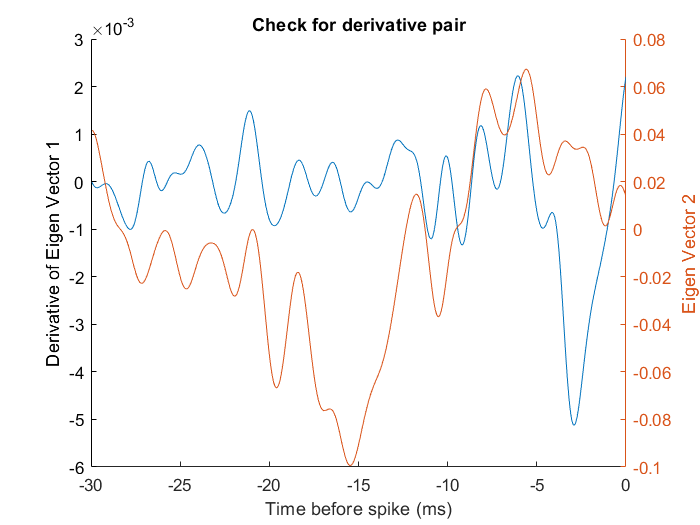

diffEVec1Norm = diff(eVec1)/max(diff(eVec1));
eVec2Norm = eVec2/max(eVec2);
figure;
plot(t(2:end), diff(eVec1)); hold on;
ylabel('Derivative of Eigen Vector 1');
yyaxis right; plot(t(2:end), eVec2(2:end));
ylabel('Eigen Vector 2');
xlabel('Time before spike (ms)');
ax=gca;
ax.Box = 'off';
title("Check for derivative pair")

% legend("d/dt (Eigen Vector 1)", "Eigen Vector 2","Location","best");

% figure;
% plot(diff(eVec1)); hold on;
% yyaxis right; plot(-eVec2);
% legend("d/dt (Eigen Vector 1)", "-Eigen Vector 2","Location","best");

% corrcoef(diffEVec1Norm,eVec2Norm(2:end))